# 22 Surface Laplacian

Spatial filters are created by defining weights for each electrode such that the weighted sum of activity at all electrodes helps highlight aspects of the signal that are present but difficult to isolate in the spatially unfiltered data. Differences among spatial filters arise from the type of information that is used when constructing the weights: 

- The surface Laplacian defines weights according to interelectrode distances. 

- Principal components analysis defines weights according to patterns of interelectrode covariances.

- Beamforming define weights based both on electrode activity and on physical electrode positions.

## 22.1 What Is the Surface Laplacian?

The surface Laplacian is a spatial bandpass filter that increases topographical selectivity by effectively filtering out spatially broad features of the data. Spatially broad topographical features are likely to reflect volume-conducted potentials or distributed but highly coherent cortical sources. Surface Laplacian-transformed data estimate the potential at the dura. After application of the surface Laplacian transform, high-spatial-frequency activity is preserved, whereas low-spatial-frequency activity is attenuated.

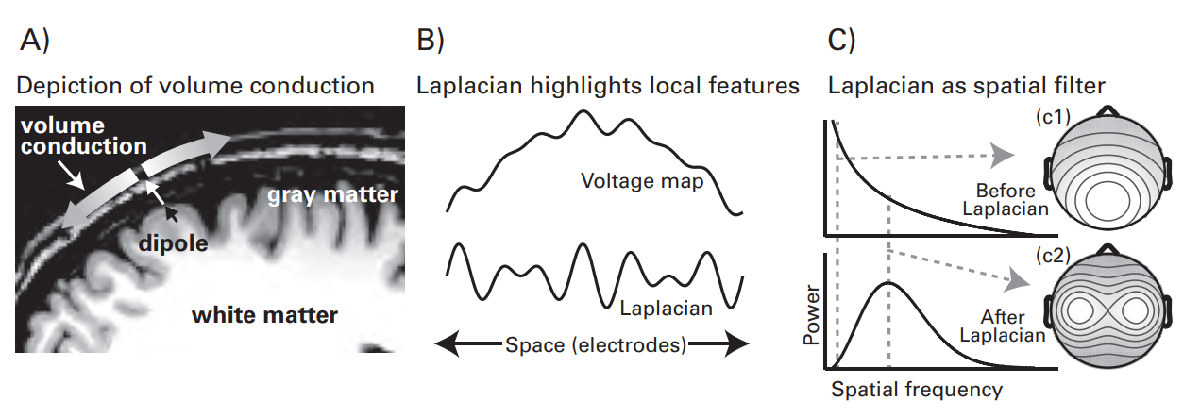

**Figure 22.1**

*Conceptual overview of the motivations for and consequences of the surface Laplacian applied to EEG data.*

In the literature you may also see the terms:

- surface current density (SCD)

- current source density (CSD)

- current scalp density (CSD) 

The term "source" here refers to sources and sinks of electrical activity at the level of the skull, not the putative brain regions that produce the scalp-recorded data. The CSD can be obtained via the surface Laplacian or by one of several other methods. The main difference between calling the spatial filter a CSD or a surface Laplacian is that with the former you are implicitly assuming that the resulting topographical distribution identifies locations of sources and sinks of electrical currents on the head, whereas with the latter you are simply describing the mathematical transform that was applied to the data. The surface Laplacian should be applied only to EEG (not MEG) data, and preferably to EEG data with 64 or more electrodes.

There are several advantages of computing and basing analyses on the surface Laplacian: 

- The surface Laplacian improves topographical localization.

- The surface Laplacian minimizes volume-conduction effects, which makes the surface Laplacian attractive for electrode-level connectivity analyses.

- The surface Laplacian is reference independent because it is computed based on the second spatial derivative of the potentials. 

- The surface Laplacian requires few parameters or assumptions, including assumptions about the locations of brain sources that are measured by scalp electrodes.

The Laplacian is more sensitive to radial dipoles than it is to tangential dipoles. Pyramidal cells that generate EEG are generally aligned perpendicular to the cortex regardless of cortical folding with respect to the skull. Thus, dipoles located in the sulci are farther away from the skull and will produce field potentials that have broader spatial distributions. Thus, activity seen in the surface Laplacian is dominated (although not necessarily entirely driven) by radial dipoles in gyral crowns.

The main disadvantage of the surface Laplacian is a by-product of its advantage. This has two implications:

- Results obtained via the surface Laplacian are likely to have been generated by relatively local and superficial sources. 

- The surface Laplacian should not be applied if you expect the results to be driven by deep sources such as the insula or by spatially distributed and highly temporally coherent generators.

The Laplacian must be applied to time-domain data. If you use the surface Laplacian only for improved topographical localization of an ERP effect, you can apply the surface Laplacian to the ERP rather than to the single-trial data. Finally, the surface Laplacian must be applied to all of the data or to none of the data

The "raw" units of the surface Laplacian are microvolts per square millimeter $(\mu V/mm^2 )$, which is often converted to square centimeters. This is because the surface Laplacian is the second spatial derivative of the topographical activity. However, the magnitude of these values should not be overinterpreted. For many time-frequency analyses that involve phase values or that use baseline normalization, the unit is not important because the data become rescaled to percentage change, decibels, or other values.

Because the surface Laplacian is based on spatial sampling and spatial weighting, the number of electrodes you have is important for the accuracy of the surface Laplacian. In general, having more electrodes is better. Sixty-four electrodes is a reasonable minimum, and >100 electrodes will provide more accurate results. Typically, the surface Laplacian is computed using standard electrode locations, but there are methods to use individual skull shape and precise electrode positions to improve the accuracy of surface Laplacian.

## 22.2 Algorithms for Computing the Surface Laplacian for EEG Data

A basic approximation to the surface Laplacian is to subtract from each electrode the averaged activity of immediately surrounding electrodes. However, the effect of volume conduction does not affect all neighboring electrodes equally but, rather, as a function of the distance between each electrode and the "source" electrode (that is, the skull/surface source of the electrical activity).

There are several algorithms to compute the surface Laplacian that are more accurate than nearest-neighbor subtraction. The computation of the surface Laplacian must be related to the spherical spatial derivative:

- Some solutions, often call deblurring or dura imaging, rely on three- or four-shell spherical or realistic head models with specified electrical conductivities at the different head tissues . 

- Other solutions are based on spherical spline interpolations and make no assumptions about the conductivity of head tissues. 

It can be shown that many solutions to the surface Laplacian provide qualitatively similar and in some cases nearly identical results.

Here, the spherical spline method by Perrin and colleagues is presented. This method is faster than the "New Orleans" method discussed in the Nunez and Srinivasan (2006) book while giving nearly identical results.

The first step in computing the Laplacian is to compute the G and H matrices. These are electrode-by-electrode weighting matrices that are used in the Laplacian computation:

### 
$$G_{ij} =(4\pi )^{-1} \sum_{n=1}^{order} \frac{(2n+1)P_n (cosdist_{ij} )}{(n(n+1))^m }$$


### 
$$H_{ij} =(4\pi )^{-1} \sum_{n=1}^{order} \frac{-2(n+1)P_n (cosdist_{ij} )}{(n(n+1))^{m-1} }$$


- $G_{ij}$ is the element of the G weighting matrix between electrode i and electrode j used in the surface Laplacian computation

- $H_{ij}$ is the element of the H weighting matrix between electrode i and electrode j used in the surface Laplacian computation

- $4\pi$ is a spherical geometric normalization factor

- $n$ is the index and order term for the Legendre polynomial, defining the spatial harmonic frequencies

- $order$ is the maximum upper limit of the Legendre polynomial summation expansion

- $P_n$ is the Legendre polynomial evaluated based on spherical coordinate distances between electrodes

- $cosdist_{ij}$ is the cosine distance between electrode i and electrode j on a normalized unit-radius sphere

- $m$ is a constant positive integer smoothing parameter that controls the spatial frequency selectivity and smoothness of the result

Values of m from 2 to 6 are reasonable, and it can be fixed at 4, or 3 for high-density (>100 electrodes) recordings. Smaller values will produce results that contain only very high spatial frequencies, whereas larger values will produce results that contain only very low spatial frequencies.

A larger order parameter will increase the accuracy of the G and H matrices. Perry et al. recommend an order of 7. With 64 electrodes the accuracy seems to improve until an order of around 10, with little improvement or change in the G and H matrices (but longer computation time) beyond 10. However, as the order becomes large, only very high spatial frequencies can pass through the filter. This may impede cross-subject averaging and comparisons. Thus, the Legendre polynomial order should be set to a value that is high enough to isolate high-spatial-frequency activity but not so high as to isolate only extremely high spatial frequencies that will reflect activity only at single electrodes.

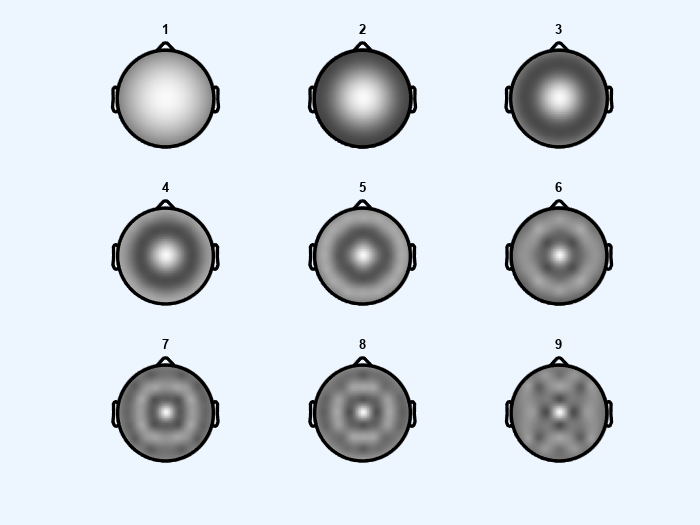

load sampleEEGdata

X = [EEG.chanlocs.X];
Y = [EEG.chanlocs.Y];
Z = [EEG.chanlocs.Z];

[~, ~, spherical_radii] = cart2sph(X, Y, Z);
maxrad = max(spherical_radii);
x = X ./ maxrad;
y = Y ./ maxrad;
z = Z ./ maxrad;


cz_idx = find(strcmpi('Cz', {EEG.chanlocs.labels}));
cosdist = 1 - (((x(cz_idx) - x).^2 + (y(cz_idx) - y).^2 + (z(cz_idx) - z).^2) / 2);

legpoly = zeros(9, EEG.nbchan);
for ni = 1:9
    temp = legendre(ni, cosdist);
    legpoly(ni, :) = temp(1, :);
end

figure;
for i = 1:9
    subplot(3, 3, i);
    topoplot(legpoly(i, :), EEG.chanlocs, 'plotrad', 0.53, 'electrodes', 'off', 'numcontour', 0);
    colormap(gray);
    title(num2str(i));
end

**Figure 22.2**

*Topographical illustration of the Legendre polynomial "seeded" from electrode Cz.*

The $cosdi\textrm{st}$ term is computed according to the following equation:

### 
$$cosdist_{ij} =1-\frac{(X_i -X_j )^2 +(Y_i -Y_j )^2 +(Z_i -Z_j )^2 }{2}$$


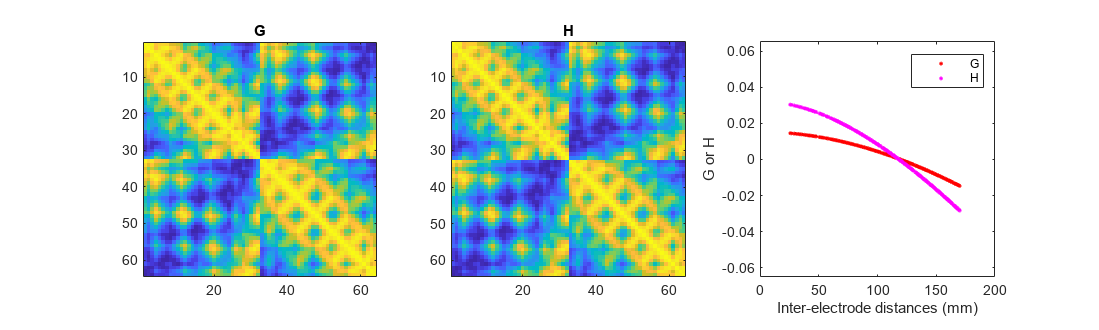

interelectrodedist=zeros(EEG.nbchan);
for chani=1:EEG.nbchan
    for chanj=chani+1:EEG.nbchan
        interelectrodedist(chani,chanj) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chanj).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chanj).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chanj).Z)^2);
    end
end

valid_gridpoints = find(interelectrodedist);

[junk,G,H] = laplacian_perrinX(rand(size(X)),X,Y,Z,[],1e-6);

figure(Position=[100,100,1000,300])

subplot(131)
imagesc(G)

axis square
title('G')

subplot(132)
imagesc(H)
axis square
title('H')

subplot(133)
plot(interelectrodedist(valid_gridpoints),G(valid_gridpoints),'r.')
hold on
plot(interelectrodedist(valid_gridpoints),H(valid_gridpoints),'m.')
legend({'G';'H'})
set(gca,'ylim',[-.065 .065])
xlabel('Inter-electrode distances (mm)'), ylabel('G or H')
axis square

**Figure 22.3**

*G and H weighting matrices.*

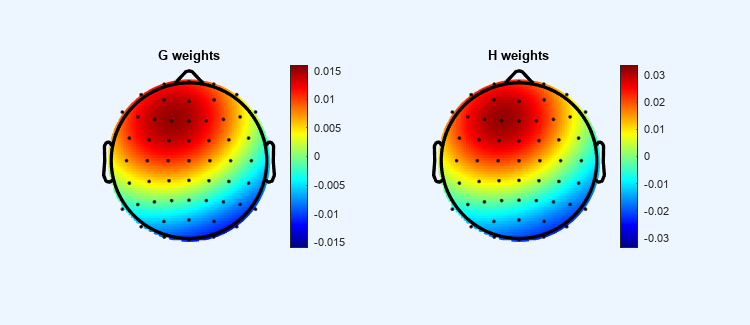

seed_chan = 'F1';
seed_idx = find(strcmpi(seed_chan, {EEG.chanlocs.labels}));

g_weights = G(seed_idx, :);

h_weights = H(seed_idx, :);

max_g = max(abs(g_weights));
max_h = max(abs(h_weights));

figure('Position', [100, 100, 600, 260]);

subplot(1, 2, 1);
topoplot(g_weights, EEG.chanlocs, 'plotrad', 0.53, 'maplimits', [-max_g, max_g], 'numcontour', 0);
title('G weights');
colorbar;

subplot(1, 2, 2);
topoplot(h_weights, EEG.chanlocs, 'plotrad', 0.53, 'maplimits', [-max_h, max_h], 'numcontour', 0);
title('H weights');
colorbar;

**Figure 22.4**

*Topographical projection of the spatial weighting profiles extracted from the *$G$* and *$H$* matrices seeded at electrode Cz.*

You may have noticed that, so far, no data have been introduced to the equations in this chapter. The G and H matrices are based entirely on interelectrode distances and specified spatial frequency ranges, and are not related to the time-series data.

Once the G and H matrices are created, they are then used to compute the Laplacian:

### 
$$lap_i =\sum_{j=1}^{nelec} C_i H_{ij}$$


- $lap_i$ is the Laplacian for electrode i at one time point 

- $j$ is each other electrode

- $\textrm{nelec}$ is the total number of electrodes

- $H_{ij}$ is the element in the H matrix corresponding to electrodes i and j

- $C$ is where the data are finally introduced

### 
$$C_i =d_i -\frac{\sum_{j=1}^{nelec} d_j }{\sum_{j=1}^{nelec} Gs_{ij}^{-1} }Gs_i^{-1}$$


### 
$$d_i =data_i^{-1} Gs$$


### 
$$Gs=G+\lambda$$


- $C_i$ is an intermediate vector where the time-series data are finally introduced into the calculation

- $d_i$ is an intermediate term representing the data multiplied by the inverse of the smoothed $G$ matrix

- $Gs$ is the smoothed $G$ weighting matrix

- $\lambda$ is a small positive smoothing parameter added to the diagonal elements of the $G$ matrix

In general, you should use a $\lambda$ of $10^{-5}$ for 64 electrodes; for more than 64 electrodes (e.g., 256), smaller values such as $10^{-6}$ or $5^{-6}$ might be appropriate.

The general point to notice is that a weighted sum of activity at all electrodes is subtracted from the activity of each electrode. This is done first using the G matrix, and then the result is scaled again using the H matrix. Hence, it is a second spatial derivative.

These equations are presented as if the Laplacian is computed separately for each electrode and for each time point, but this is merely to facilitate explanation. In fact, the Laplacian can be computed simultaneously for all electrodes and for all time points using matrix algebra. Because the Laplacian transform is based on space and not on time, there are no edge artifacts as there are for temporal filtering.

## 22.3 Surface Laplacian for Topographical Localization

The surface Laplacian will help isolate topographical features to within several square centimeters. This is because spatially broad topographical components that are driven by deep or powerful volume-conducted sources are generally outside the spatial frequency range of the Laplacian filter and are therefore attenuated.

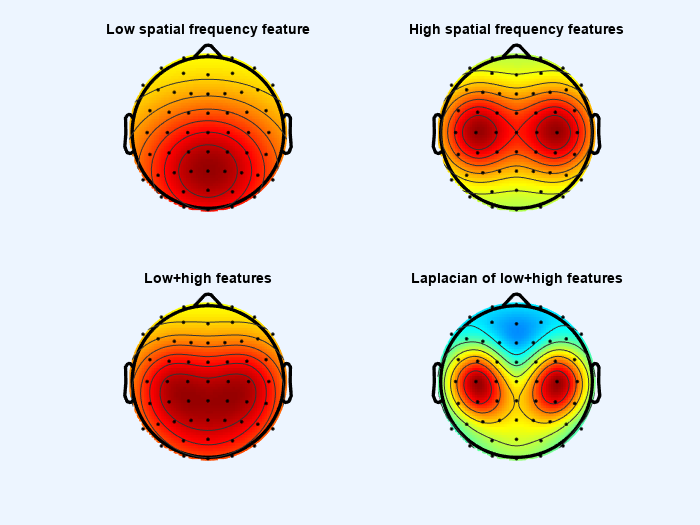

chan1 = 'pz';
chan2 = 'c4';
chan3 = 'c3';

eucdist1 = zeros(1,64);
eucdist2 = zeros(1,64);
eucdist3 = zeros(1,64);

chan1idx = strcmpi(chan1,{EEG.chanlocs.labels});
chan2idx = strcmpi(chan2,{EEG.chanlocs.labels});
chan3idx = strcmpi(chan3,{EEG.chanlocs.labels});

for chani=1:EEG.nbchan
    eucdist1(chani) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chan1idx).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chan1idx).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chan1idx).Z)^2 );
    eucdist2(chani) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chan2idx).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chan2idx).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chan2idx).Z)^2 );

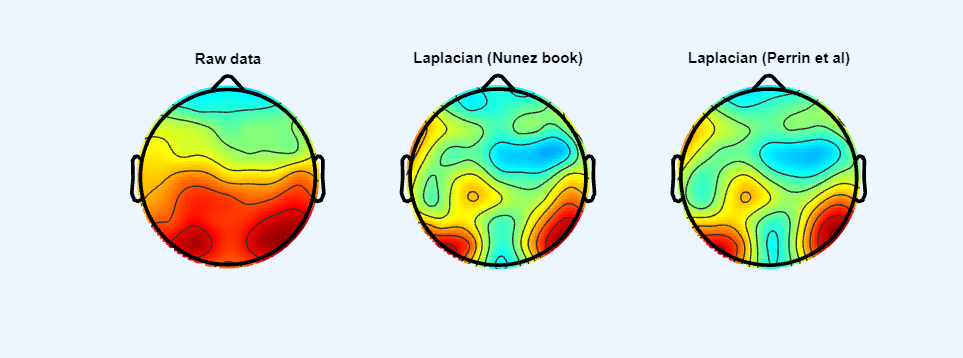

    eucdist3(chani) = sqrt( (EEG.chanlocs(chani).X-EEG.chanlocs(chan3idx).X)^2 + (EEG.chanlocs(chani).Y-EEG.chanlocs(chan3idx).Y)^2 + (EEG.chanlocs(chani).Z-EEG.chanlocs(chan3idx).Z)^2 );
end

hi_spatfreq  = 2*exp(- (eucdist1.^2)/(2*95^2) ); 
lo_spatfreq  =   exp(- (eucdist2.^2)/(2*50^2) )  +  exp(- (eucdist3.^2)/(2*50^2) );
surf_lap_all = laplacian_perrinX(hi_spatfreq+lo_spatfreq,X,Y,Z);

figure
subplot(221)
topoplot(hi_spatfreq,EEG.chanlocs,'plotrad',.53);
title('Low spatial frequency feature')

subplot(222)
topoplot(lo_spatfreq,EEG.chanlocs,'plotrad',.53);
title('High spatial frequency features')

subplot(223)
topoplot(hi_spatfreq+lo_spatfreq,EEG.chanlocs,'plotrad',.53);
title('Low+high features')

subplot(224)
topoplot(surf_lap_all,EEG.chanlocs,'plotrad',.53);
title('Laplacian of low+high features')

**Figure 22.5**

*Simulated data showing the effect of the surface Laplacian on features of different spatial frequencies.*

Because the surface Laplacian attenuates low-spatial-frequency features, it will also attenuate artifacts that contaminate your data if those artifacts are characterized by low spatial frequencies. The blink and other EOG artifacts are examples of this. EOG artifacts have a fairly broad spatial topography and are therefore attenuated after the surface Laplacian. This might be useful in situations in which an independent components analysis could not cleanly isolate all of the EOG activity. This feature of the surface Laplacian is particularly beneficial if you will examine activity at anterior electrodes and want to be confident that EOG activity does not contaminate the results.

Spatially unfiltered data and the surface Laplacian show different cortical electrical features: 

- Spatially unfiltered topographies tend to be dominated by large-amplitude, low-spatial-frequency (and thus, likely volume-conducted) sources. 

- Surface Laplacian topographies are driven by local sources that may be smaller in amplitude.

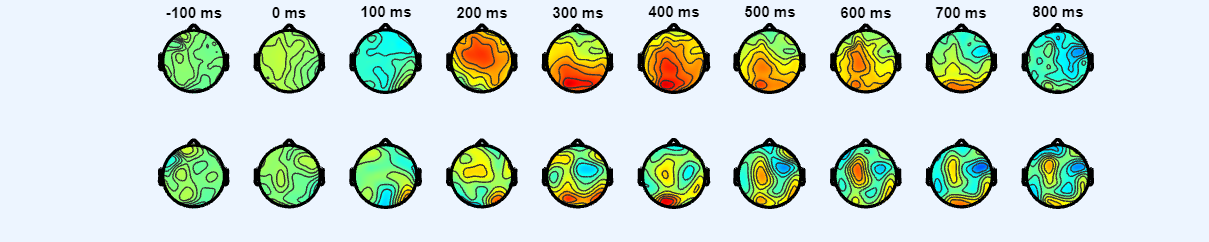

data2use = double(mean(EEG.data(:,321,:),3));

surf_lapN = laplacian_nola(X,Y,Z,data2use,100);
surf_lapP = laplacian_perrinX(data2use,X,Y,Z,[],1e-5); 

figure('Position', [100, 100, 700, 260]);

subplot(131)
topoplot(data2use,EEG.chanlocs,'plotrad',.53,'electrodes','off');
title('Raw data')

subplot(132)
topoplot(surf_lapN,EEG.chanlocs,'plotrad',.53,'electrodes','off');
title('Laplacian (Nunez book)')


subplot(133)
topoplot(surf_lapP,EEG.chanlocs,'plotrad',.53,'electrodes','off');
title('Laplacian (Perrin et al)')

**Figure 22.6**

*The effect of the surface Laplacian on real data (the ERP from 246 ms post-stimulus onset).*

times2plot = -100:100:800;

figure('Position', [100, 100, 1000, 200]);

for i=1:length(times2plot)
    
    [junk,timeidx] = min(abs(EEG.times-times2plot(i)));
    
    tempdata = double(squeeze(mean(EEG.data(:,timeidx,:),3)));
    
    subplot(2,length(times2plot),i)
    topoplot(tempdata,EEG.chanlocs,'plotrad',.53,'maplimits',[-10 10],'electrodes','off');
    title([num2str(times2plot(i)) ' ms' ])
    
    subplot(2,length(times2plot),i+length(times2plot))
    topoplot(laplacian_perrinX(tempdata,X,Y,Z),EEG.chanlocs,'plotrad',.53,'maplimits',[-40 40],'electrodes','off');
end

**Figure 22.7**

*Comparison of spatially unfiltered voltage topographies (top row) and surface Laplacians (bottom row) of the same data.*

In the comparison of spatially unfiltered and surface Laplacian topographies, there are three possible results: 

- The topographical activity appears similar in both the spatially unfiltered data and the surface Laplacian. This suggests that the activity was locally generated and was not overpowered by larger, volume-conducted components.

- There are topographical patterns visible in the surface Laplacian that are not visible, or are difficult to visualize, in the spatially unfiltered data. This suggests that there are local cortical dynamics that are overshadowed by volume-conducted effects.

- There can be topographical patterns visible in the spatially unfiltered data that are not visible in the Laplacian. This suggests that that spatial pattern reflects volume-conducted activity.

When the topographies of the spatially unfiltered data and the surface Laplacian differ, the time courses of activity at the same electrode will be different.

## 22.4 Surface Laplacian for Connectivity Analyses

Applying the surface Laplacian to EEG data helps render the data appropriate for connectivity analyses. This is because the surface Laplacian minimizes volume-conducted effects that are a potential source of spurious connectivity results.

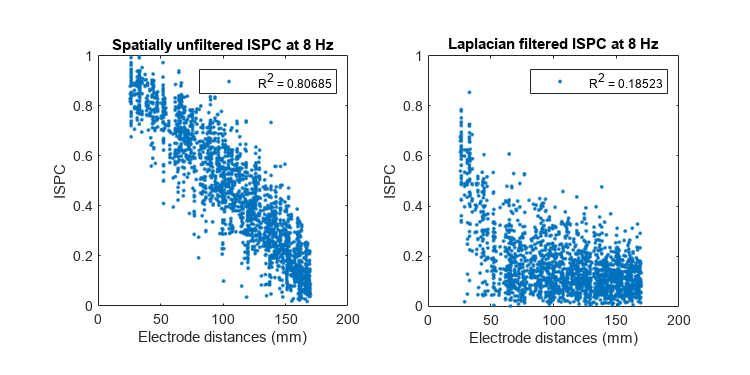

lap_data = laplacian_perrinX(EEG.data,X,Y,Z);

freq2use =   8;
time2use = 400;

time          = -1:1/EEG.srate:1;
n_wavelet     = length(time);
n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv2       = pow2(nextpow2(n_convolution));

wavelet_fft = fft(exp(2*1i*pi*freq2use.*time) .* exp(-time.^2./(2*(4/(2*pi*freq2use))^2))/freq2use,n_conv2);
half_of_wavelet_size = (length(time)-1)/2;

allphases_pre = zeros(size(EEG.data));
allphases_lap = zeros(size(EEG.data));
ispc_pre = zeros(EEG.nbchan);
ispc_lap = zeros(EEG.nbchan);
timeidx  = dsearchn(EEG.times',time2use');

for chani=1:EEG.nbchan
    
    fft_data = fft(reshape(EEG.data(chani,:,:),1,EEG.pnts*EEG.trials),n_conv2);
    conv_res = ifft(wavelet_fft.*fft_data,n_conv2);
    conv_res = conv_res(1:n_convolution);
    conv_res = conv_res(half_of_wavelet_size+1:end-half_of_wavelet_size);

    allphases_pre(chani,:,:) = reshape(conv_res,EEG.pnts,EEG.trials);

    fft_data = fft(reshape(lap_data(chani,:,:),1,EEG.pnts*EEG.trials),n_conv2);
    conv_res = ifft(wavelet_fft.*fft_data,n_conv2);
    conv_res = conv_res(1:n_convolution);
    conv_res = conv_res(half_of_wavelet_size+1:end-half_of_wavelet_size);

    allphases_lap(chani,:,:) = reshape(conv_res,EEG.pnts,EEG.trials);
end

for chani=1:EEG.nbchan
    for chanj=chani+1:EEG.nbchan
        
        cd = squeeze(allphases_pre(chani,timeidx,:).*conj(allphases_pre(chanj,timeidx,:)));
        ispc_pre(chani,chanj) = abs(mean(exp(1i*angle(cd))));
        
        cd = squeeze(allphases_lap(chani,timeidx,:).*conj(allphases_lap(chanj,timeidx,:)));
        ispc_lap(chani,chanj) = abs(mean(exp(1i*angle(cd))));

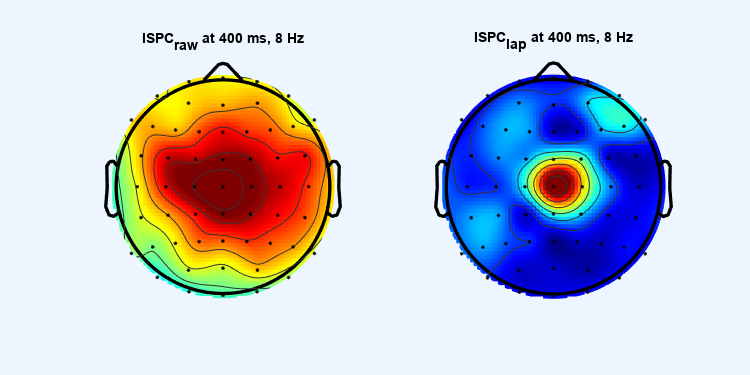

    end
end

ispc_pre = ispc_pre + ispc_pre' + eye(EEG.nbchan);
ispc_lap = ispc_lap + ispc_lap' + eye(EEG.nbchan);


figure('Position', [100, 100, 600, 300]);

subplot(121)
plot(interelectrodedist(valid_gridpoints),ispc_pre(valid_gridpoints),'.')
xlabel('Electrode distances (mm)'), ylabel('ISPC')

title([ 'Spatially unfiltered ISPC at ' num2str(freq2use) ' Hz' ])
set(gca,'ylim',[0 1])
r=corr(interelectrodedist(valid_gridpoints),ispc_pre(valid_gridpoints),'type','s');
legend([ 'R^2 = ' num2str(r^2) ])
axis square

subplot(122)
plot(interelectrodedist(valid_gridpoints),ispc_lap(valid_gridpoints),'.')
xlabel('Electrode distances (mm)'), ylabel('ISPC')
title([ 'Laplacian filtered ISPC at ' num2str(freq2use) ' Hz' ])
set(gca,'ylim',[0 1])
r=corr(interelectrodedist(valid_gridpoints),ispc_lap(valid_gridpoints),'type','s');
legend([ 'R^2 = ' num2str(r^2) ])
axis square

**Figure 22.8**

*Panel A shows that without any spatial filtering, interelectrode connectivity strength (here measured through ISPC, a phase-based measure of connectivity) is strongly predicted by interelectrode distance; panel B shows that this connectivity is largely decoupled from distance after application of the surface Laplacian, except at very short distances.*

figure('Position', [100, 100, 600, 300]);

subplot(121)
topoplot(ispc_pre(48,:),EEG.chanlocs,'maplimits',[0 .8],'plotrad',.53);
title([ 'ISPC_r_a_w at ' num2str(time2use) ' ms, ' num2str(freq2use) ' Hz' ])

subplot(122)
topoplot(ispc_lap(48,:),EEG.chanlocs,'maplimits',[0 .8],'plotrad',.53);
title([ 'ISPC_l_a_p at ' num2str(time2use) ' ms, ' num2str(freq2use) ' Hz' ])

**Figure 22.9**

*Seeded connectivity from electrode Cz. The grayscale intensity shows the strength of connectivity between Cz and each other electrode. *

It is important to stress that the surface Laplacian does not guarantee that all volume-conduction effects are eliminated. Thus, it is not the case that you can simply apply the surface Laplacian and then be confident that volume conduction will never produce spurious connectivity results.

## 22.5 Surface Laplacian for Cleaning Topographical Noise

Although the surface Laplacian is sometimes referred to as a high-pass spatial filter, it is actually a bandpass spatial filter. This means that the surface Laplacian will remove not only low-spatial-frequency components but also very-high-spatial-frequency components.

With high-density EEG (>100 electrodes and, in particular, 256 electrodes), the spatial resolution is high enough that the bandpass spatial filter property of the surface Laplacian can be observed. This can be useful for cleaning some topographical noise. Because single-electrode noise spikes have a high spatial frequency, they are attenuated by the surface Laplacian.

Applying the surface Laplacian should not be relied on as an excuse for collecting noisy data, nor should it replace normal data-cleaning and preprocessing protocols. However, this feature of the Laplacian is another advantage of its application as a processing tool for use in data analyses, particularly for high-density EEG caps. As mentioned earlier in this chapter, the surface Laplacian must be applied to all data or to no data; you cannot apply the surface Laplacian to only a few noisy time points.

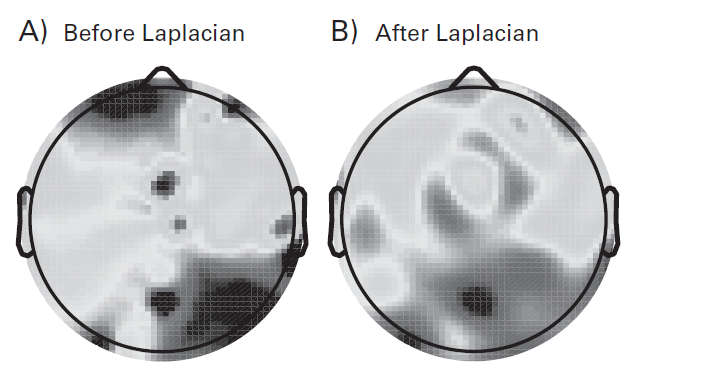

**Figure 22.10**

*The surface Laplacian attenuates high-spatial-frequency features in addition to low-spatial-frequency features.*

## 22.6 Describing This Analysis in Your Methods Section

Perhaps most importantly, you should state the purpose of applying the surface Laplacian to your data

- To increase topographical localization.

- To facilitate electrode-level connectivity analyses.

- To attenuate volume-conducted features of the data that overshadow the effects you might be interested in investigating. 

If you examined the results with and without the surface Laplacian, state whether any patterns of results changed in qualitative ways.

There are several algorithms for computing the surface Laplacian; be clear about which algorithm you used. It is not necessary to write out all of the equations for the Laplacian unless you make modifications to the algorithm. If you used nondefault parameters, for example for smoothing the G matrix, state the values of the parameters you used and justify the departure from commonly used parameter values.